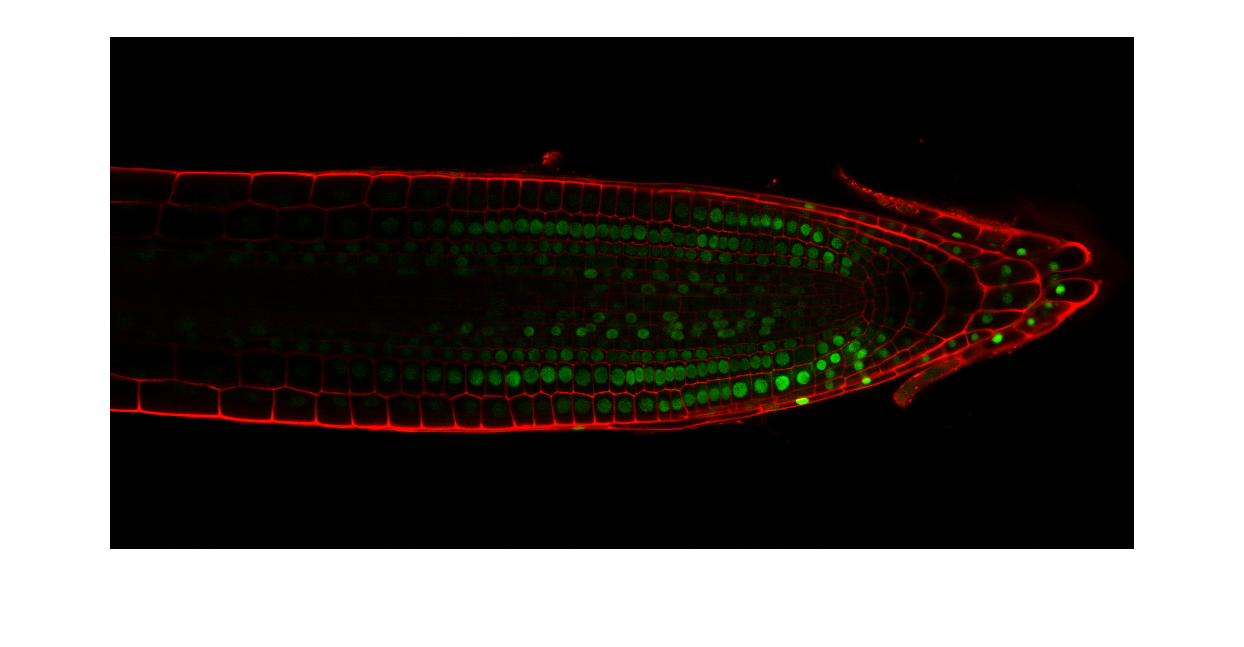

% Loads image
atrium = imread('StackNinja3.bmp');
imshow('StackNinja3.bmp');

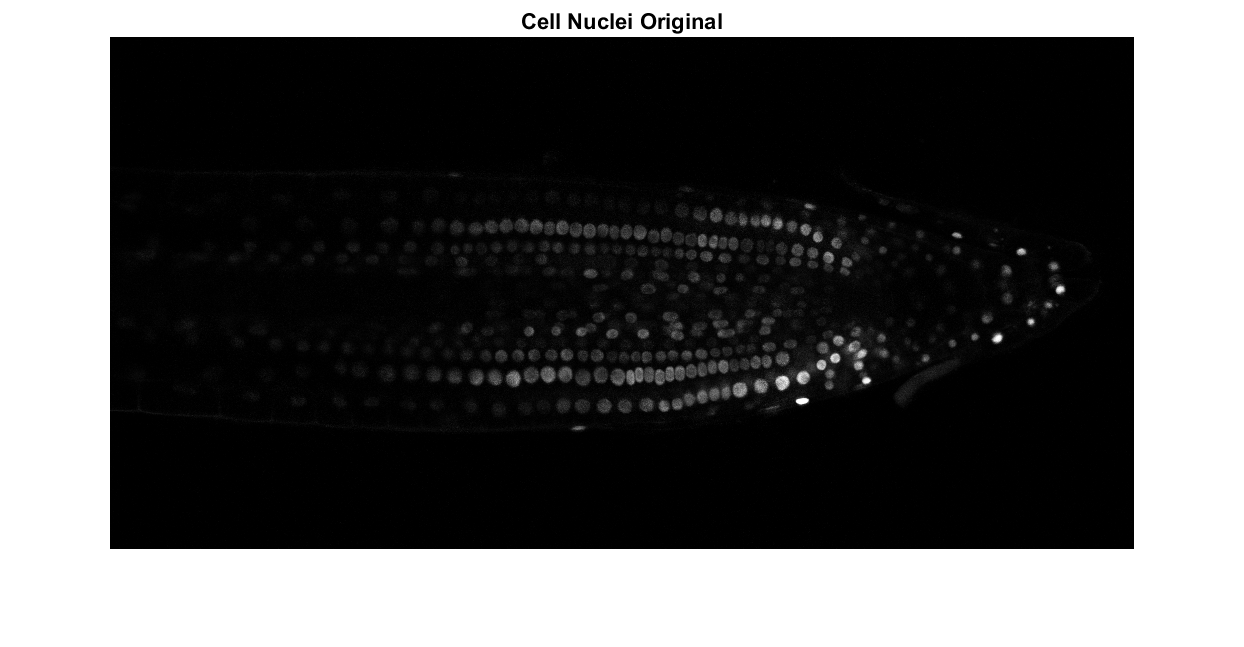


%Colour space
G = atrium(:,:,2);
imshow(G);
title('Cell Nuclei Original');

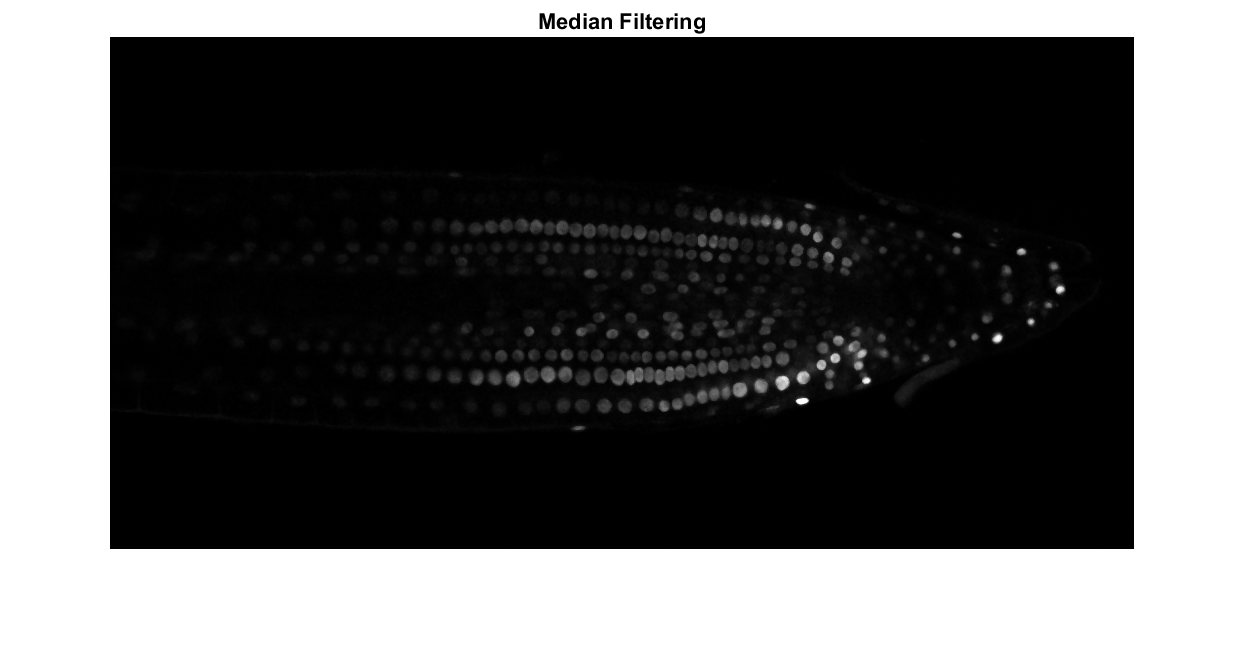

 

%Noise Reduction
mf= medfilt2(G);
imshow(mf);
title('Median Filtering');

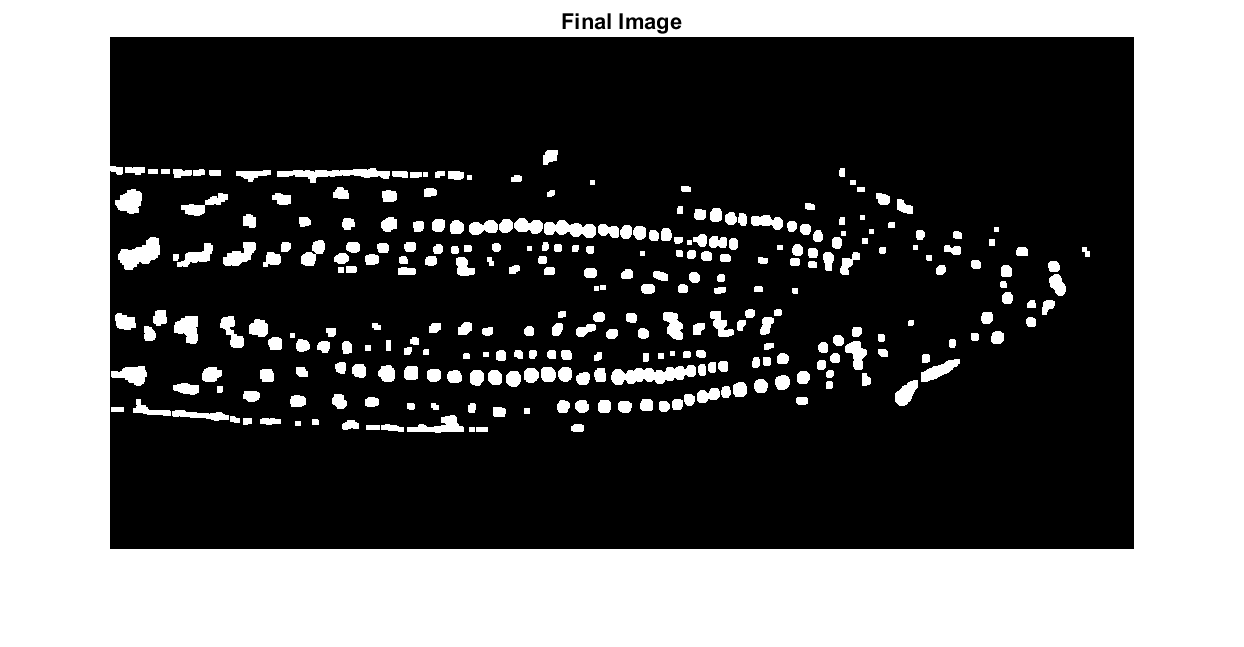


%local adaptive thresholding
T = adaptthresh(mf,0.1);      


%Binary Image Processing
binary = imbinarize(mf,T);
se = strel('disk',3,6);                           
er = imerode(binary, se);
d = imdilate(er,se);
imshow(d);
title('Final Image')

countdc = bwconncomp(d);
countdc

countdc = struct with fields:
    Connectivity: 8
       ImageSize: [512 1024]
      NumObjects: 280
    PixelIdxList: {1×280 cell}


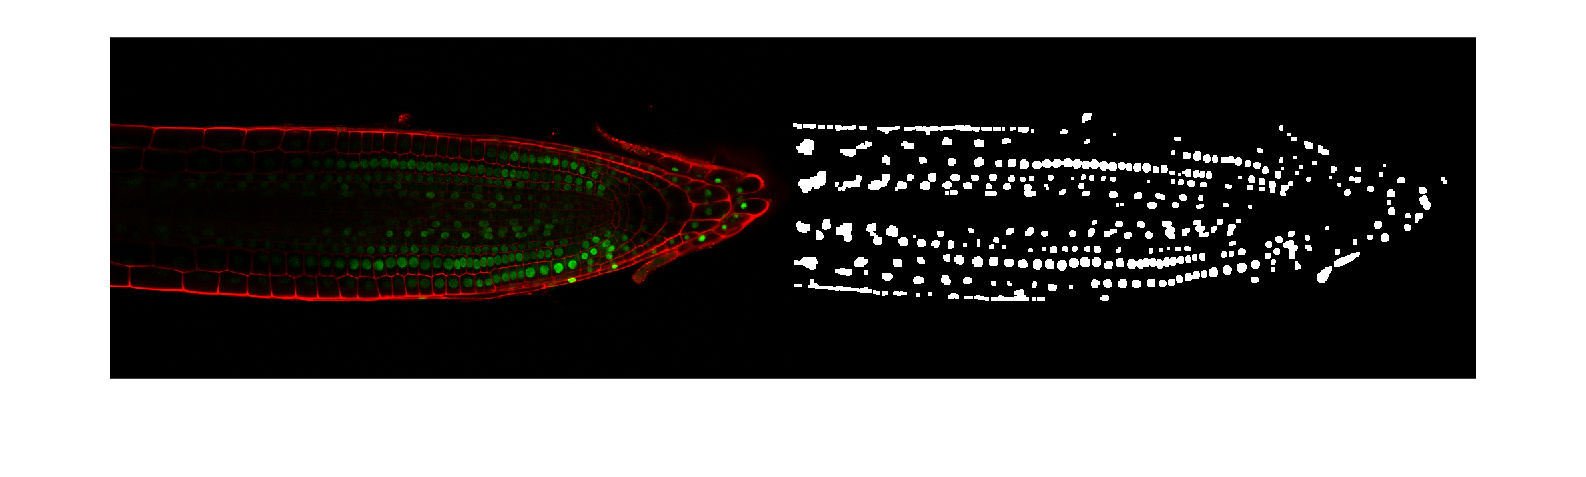

imshowpair(atrium,d,'montage');